cellFluoIntensityEvolutionPlot2_ForCxy

Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
Thickness Breaking up long cells(0).
T

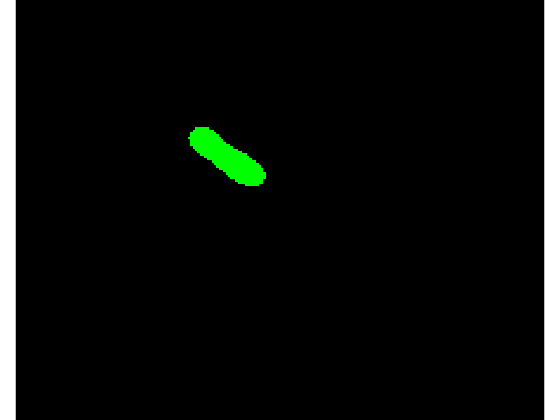

imageStack = import_tiff_stack('\\192.168.1.33\d\cxy\20201230cxy\B0034-mch2-2-2\mch2.tif');

imagemasks = fluoImCellSeg_ys(imageStack);


for iFrame = 1 :size(imagemasks,3)
    stats = regionprops(imagemasks(:,:,iFrame),imageStack(:,:,iFrame),...
        'MeanIntensity','MaxIntensity','Centroid');
    cellInfo{iFrame} = stats;
end


a = [];
f1 = figure,

f1 =   Figure (24) - 属性:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  显示 所有属性


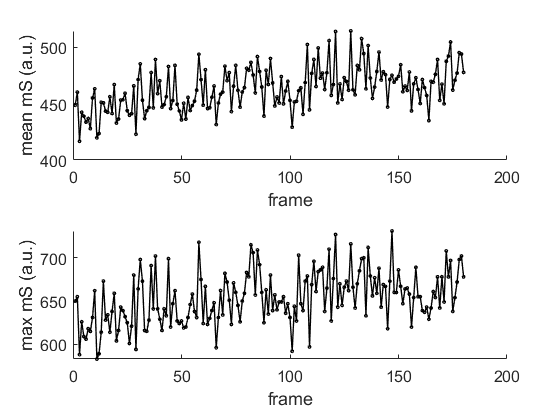


for i = 1:180
    a(i,1) = cellInfo{i}.MeanIntensity; 
    a(i,2) = cellInfo{i}.MaxIntensity; 
end

subplot(2,1,1),
line(1:180,a(:,1),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );

subplot(2,1,2),
line(1:180,a(:,2),'MarkerSize',2,'Marker','o','Color','black','LineWidth',1 );




subplot1 = subplot(2,1,1,'Parent',f1);
hold(subplot1,'on')
set(subplot1,'FontSize',12);
box(subplot1,'off');
% legend(subplot1,'show');
hold(subplot1,'off')
ylabel({'mean mS (a.u.)'});
xlabel({'frame'});

subplot2 = subplot(2,1,2,'Parent',f1);
hold(subplot2,'on')
set(subplot2,'FontSize',12);
box(subplot2,'off');
% legend(subplot2,'show');
hold(subplot2,'off')
ylabel({'max mS (a.u.)'});
xlabel({'frame'});